# Entregable final - Modelación computacional de sistemas eléctricos

**Realizado por:**

Liliana Solórzano Pérez | A01641392 

Armando Terrazas Gómez | A01640924 

Andrea Núñez García | A01640839 

Fernando Gómez Martínez | A01641228 

clear; close all; clc; clearvars; %borrar variables, pantalla

%Genera el número de cargas tanto positivas como negativas
numeroCargas = 4;

%Se define que el número de cargas positivas va a ser igual al número de
%cargas negativas y va a avanzar de uno en uno.
qPos = 1:numeroCargas;
qNeg = qPos;

Width = 2;
Height = 20; %Tamaño placa Positiva
xRect = -9;


#### **Graficamos las placas positivas y negativas en 3D**

%Graficar placa positiva
BoxPlot3(xRect,0,-Height/2,Width,Width,Height,[1 0 0]);
hold on;

%Graficar placa negativa
Height_Neg = 14; %Tamaño placa Negativa
BoxPlot3(-xRect,0,-Height_Neg/2,Width,Width,Height_Neg,[0 0 1]); %función creada para crear cajas en 3D, ver el final del documento


#### Crear un globulo rojo en 3D

n = 25;

%aleatoria randi ([1 5],1, 1) limite inferior y superior, una fila y una
%columna
xc = randi([-9 10],1,1); %movimiento en x
yc= randi([1 9],1,1); %movimiento en y
zc = randi([1 7],1,1); %movimiento en z

xr = 2; %radio del glóbulo en x
yr = 1; %radio del glóbbulo en y
zr=2; %altura del glóbbulo

[x,y,z]= ellipsoid(xc,yc,zc,xr,yr,zr,n);
mycolors = [1 0 0; 1 0 0; 1 0 0]; %se define el color del glóbulo
colormap(mycolors);
axis equal
surf(x,y,z)


#### Graficar posición de cargas con sus respectivos signos

%Definimos las coordenadas donde se van a encontrar las cargas positivas y
%negativas de las placas
posicionQ_pos = linspace(-Height/2,Height/2,length(qPos)+2)

posicionQ_pos =    -10    -6    -2     2     6    10


posicionQ_neg = linspace(-Height_Neg/2,Height_Neg/2,length(qNeg)+2)

posicionQ_neg =    -7.0000   -4.2000   -1.4000    1.4000    4.2000    7.0000



%Graficamos los signos positivo o negativo dependiendo de la carga de la
%placa
for charge = 2:length(posicionQ_pos)-1
    text(xRect-0.75,Width/2,posicionQ_pos(charge)+0.5,'+','FontSize',20,'Color','white');
    text(-xRect-0.8,Width/2,posicionQ_neg(charge)+0.5,'-','FontSize',30,'Color','white');
end

#### Crear el campo Vectorial

%Definimos los parámetros para el campo vectorial de 3D
X = -20:2:20;
Y = -20:2:20;
Z = -20:2:20;

%Creamos la malla del campo donde x, y , z van a ser nuestras variables
%donde se va a guardar nuestras coordenadas de los vectores
[x,y,z] = meshgrid(X,Y,Z);


%Campo eléctrico inicializado en 0
Ex = 0;
Ey = 0;
Ez = 0;

%Valores constantes
Qn_magnitude = -1.602e-19; %Magnitud de la carga negativa
Qp_magnitude = 1.602e-19; %magnitud de la carga positiva

eps0 = 8.854e-12; %valor constante
kC = 1/(4*pi*eps0); %Constante coloumb
xPosition = xRect+1;
yPosition = Width/2;

%Ciclo que calcula el campo vectorial de las cargas negativas
for Qn = 1:length(qNeg)

    %aplicamos la teoría para calcular el campo eléctrico
    Rx = x - (-xPosition);
    Ry = y - yPosition;
    Rz = z - posicionQ_neg(Qn+1);
    R = sqrt(Rx.^2 + Ry.^2 + Rz.^2).^3;
    Ex = Ex + kC .* Qn_magnitude .* Rx ./ R;
    Ey = Ey + kC .* Qn_magnitude .* Ry ./ R;
    Ez = Ez + kC .* Qn_magnitude .* Ry ./ R;
end

Qpos_magnitude = 1.602e-19; %Magnitud de la carga positiva

%Ciclo que calcula el campo vectorial de las cargas positivas
for Qpos = 1:length(qNeg)

    %Calcular el campo eléctrico
    Rx = x - (xPosition);
    Ry = y - yPosition;
    Rz = z - posicionQ_pos(Qpos+1);
    R = sqrt(Rx.^2 + Ry.^2 + Rz.^2).^3;
    Ex = Ex + kC .* Qpos_magnitude .* Rx ./ R;
    Ey = Ey + kC .* Qpos_magnitude .* Ry ./ R;
    Ez = Ez + kC .* Qpos_magnitude .* Ry ./ R;
end


### **Campo eléctrico del glóbulo rojo infectado o no infectado**

E_centro = [xc yc zc]; %centro del glóbulo
E_izq = [(xc -xr), (yc - yr), zc ]; %lado izquierdo del glóbulo
E_der =[ (xc + xr), (yc - yr), zc];%lado derecho del glóbulo

%Proceso para calcular el campo eléctrico de la placa positiva con el
%glóbulo

%variables positivas
Exi_variable = 0;
Eyi_variable = 0;
Ezi_variable = 0;

%variables negativas
Exi_variable_neg = 0;
Eyi_variable_neg = 0;
Ezi_variable_neg = 0;
Total_positivo = 0;


%campo eléctrico de la placa positiva
for i=1:numeroCargas

Distancia_globulo_cargaX = (xc - xr) - xPosition;
Distancia_globulo_cargaY = (yc - yr) - yPosition;
Distancia_globulo_cargaZ = (zc) - posicionQ_pos(1,i+1);

ri = sqrt(Distancia_globulo_cargaX.^2)+(Distancia_globulo_cargaY.^2)+(Distancia_globulo_cargaZ.^2);

%Suma del campo eléctrico en x y y z
Exi= ((kC*Qp_magnitude*Distancia_globulo_cargaX)/ (ri.^3));
Exi_variable = Exi_variable + Exi;
Eyi = ((kC*Qp_magnitude*Distancia_globulo_cargaY)/ (ri.^3));
Eyi_variable = Eyi_variable + Eyi;
Ezi = ((kC*Qp_magnitude*Distancia_globulo_cargaZ)/ (ri.^3));
Ezi_variable = Ezi_variable + Ezi;

%Cálculo para el campo eléctrico del glóbbulo
Distancia_globulo_cargaX = (xc - xr) - (-xPosition);
Distancia_globulo_cargaY = (yc - yr) - yPosition;
Distancia_globulo_cargaZ = (zc) - posicionQ_neg(1,i+1);


%cargas negativas campo
Exi= ((kC*Qn_magnitude*Distancia_globulo_cargaX)/ (ri.^3));
Exi_variable = Exi_variable + Exi;
Eyi = ((kC*Qn_magnitude*Distancia_globulo_cargaY)/ (ri.^3));
Eyi_variable = Eyi_variable + Eyi;
Ezi = ((kC*Qn_magnitude*Distancia_globulo_cargaZ)/ (ri.^3));
Ezi_variable = Ezi_variable + Ezi;


E_izq_distancia_total = sqrt((Exi_variable.^2)+ (Eyi_variable.^2)+ (Ezi_variable.^2));
Total_positivo = Total_positivo + E_izq_distancia_total; %almacena las variables

end


Total_negativo = 0;

%Proceso para calcular el campo eléctrico de la placa negativa con el
%glóbulo
for i=1:numeroCargas

%Cálculo para el campo eléctrico del glóbbulo
Distancia_globulo_cargaX_negativa = xPosition - (xc + xr);
Distancia_globulo_cargaY_negativa = yPosition - (yc + yr);
Distancia_globulo_cargaZ_negativa = posicionQ_pos(1,i+1) - (zc);


ri_neg = sqrt(Distancia_globulo_cargaX_negativa.^2)+(Distancia_globulo_cargaY_negativa.^2)+(Distancia_globulo_cargaZ_negativa.^2);

%campo eléctrico positivo
Exi_neg= ((kC*Qp_magnitude*Distancia_globulo_cargaX_negativa)/ (ri_neg.^3));
Exi_variable_neg = Exi_variable_neg + Exi_neg;
Eyi_neg = ((kC*Qp_magnitude*Distancia_globulo_cargaY_negativa)/ (ri_neg.^3));
Eyi_variable_neg = Eyi_variable_neg + Eyi_neg;
Ezi_neg = ((kC*Qp_magnitude*Distancia_globulo_cargaZ_negativa)/ (ri_neg.^3));
Ezi_variable_neg = Ezi_variable_neg + Ezi_neg;

%campo eléctrico del glóbulo con las placas
Distancia_globulo_cargaX_negativa = -xPosition - (xc + xr);
Distancia_globulo_cargaY_negativa = yPosition - (yc + yr);
Distancia_globulo_cargaZ_negativa = posicionQ_neg(1,i+1) - (zc);

Exi_neg= ((kC*Qn_magnitude*Distancia_globulo_cargaX_negativa)/ (ri_neg.^3));
Exi_variable_neg = Exi_variable_neg + Exi_neg;
Eyi_neg = ((kC*Qn_magnitude*Distancia_globulo_cargaY_negativa)/ (ri_neg.^3));
Eyi_variable_neg = Eyi_variable_neg + Eyi_neg;
Ezi_neg = ((kC*Qn_magnitude*Distancia_globulo_cargaZ_negativa)/ (ri_neg.^3));
Ezi_variable_neg = Ezi_variable_neg + Ezi_neg;



E_der_distancia_total_negativa = sqrt((Exi_variable_neg.^2)+ (Eyi_variable_neg.^2)+ (Ezi_variable_neg.^2));
Total_negativo= Total_negativo + E_der_distancia_total_negativa; %almacena las variables
end

E = sqrt(Ex.^2 + Ey.^2 + Ez.^2); %Magnitud vector del campo vectorial
%normalizar el vector
%vector unitario
u = Ex./E;
v = Ey./E;
w = Ez./E;

#### **Determinar si el glóbulo esta infectado o no infectado**

Infectado_no_infectado = (abs(Total_negativo - Total_positivo) * 100)/ abs(Total_positivo);

if xc > 0
    tex = text(-3,11,19,'Infectado por Malaria','FontSize',18,'Color','r','EdgeColor','k');
else 
   tex = text(-5,11,19, 'No infectado por Malaria', 'Fontsize', 18, 'Color','g', 'EdgeColor', 'k'); 
    
end


#### Creamos cuadros de texto para que se presenten en la gráfica

dimen = [0.08 0.01 0.2 0.1];
dimen2 = [0.7 0.01 0.2 0.1];
dimen3 = [0.7 0.079 0.2 0.1];
dimen4 = [0.08 0.079 0.2 0.1];
dimen5 = [0.08 0.15 0.2 0.1];


text = Infectado_no_infectado;
text2 = '             %';
text3 = Total_negativo;
text4 = 'Total negativo';
text5 = Total_positivo ;
text6 = 'Total positivo';


a = annotation('textbox',dimen,'String',text,'FitBoxToText','on');
a2 = annotation('textbox',dimen,'String',text2,'FitBoxToText','on');
a3 = annotation('textbox',dimen2,'String',text3,'FitBoxToText','on');
a4 = annotation('textbox',dimen3,'String',text4,'FitBoxToText','on');
a5 = annotation('textbox',dimen4,'String',text5,'FitBoxToText','on');
a6 = annotation('textbox',dimen5,'String',text6,'FitBoxToText','on');


#### Graficar los vectores del campo eléctrico usando quiver

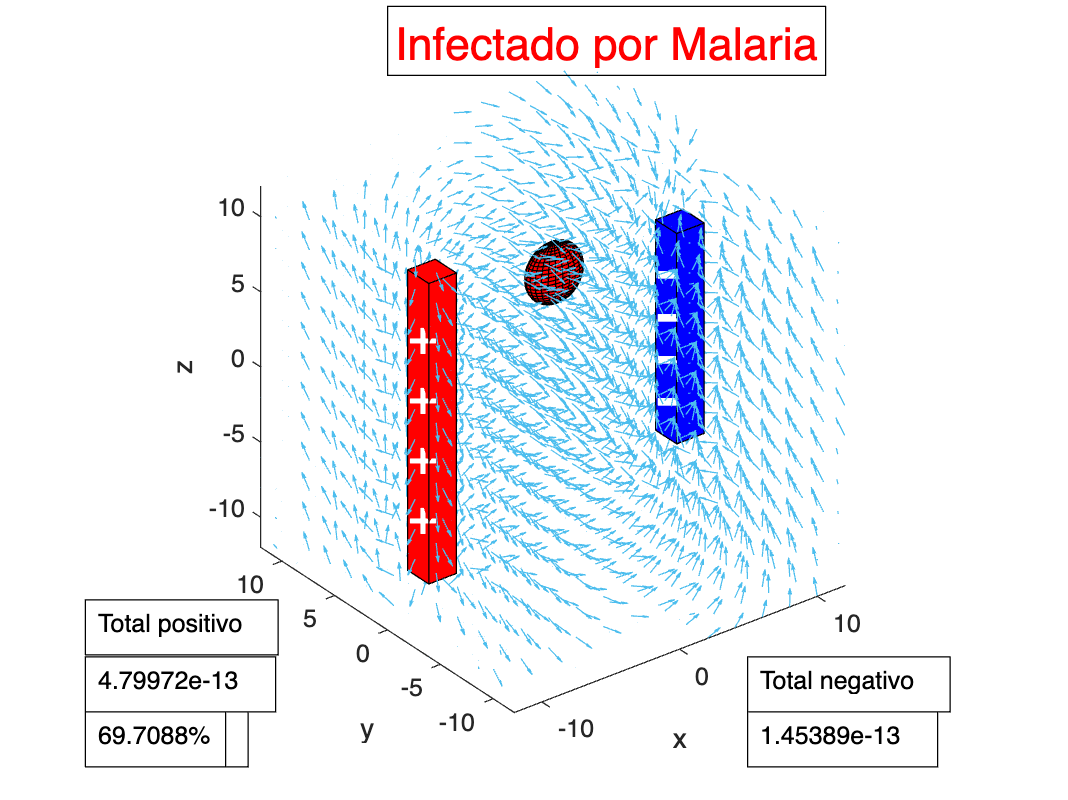

%Grafica vectores 
quiver3(x,y,z,u,v,w,'AutoScaleFactor',0.6) %AutoScale sirve para hacer los vectores más pequeños y mejor apreciables
xlim([-12 12]); ylim([-12 12]); zlim([-12 12]);
xlabel('x'); ylabel('y'); zlabel('z');

#### **Función para graficar cajas en 3D (Placa positiva y negativa): ver código en la parte superior**

function BoxPlot3(x0, y0, z0, Lx, Ly, Lz,color)
    x = [x0, x0, x0, x0, x0+Lx, x0+Lx, x0+Lx, x0+Lx]; %(1×8)
    y = [y0, y0, y0+Ly, y0+Ly, y0, y0, y0+Ly, y0+Ly]; 
    z = [z0, z0+Lz, z0+Lz, z0, z0, z0+Lz, z0+Lz, z0];

    index = zeros(6,5);
    index(1,:) = [1 2 3 4 1];
    index(2,:) = [5 6 7 8 5];
    index(3,:) = [1 2 6 5 1];
    index(4,:) = [4 3 7 8 4];
    index(5,:) = [2 6 7 3 2];
    index(6,:) = [1 5 8 4 1];
    for k = 1:6
        fill3(x(index(k,:)), y(index(k,:)), z(index(k,:)),color)        
        hold on
    end
end
